# Filtrat

### Filtres integratius

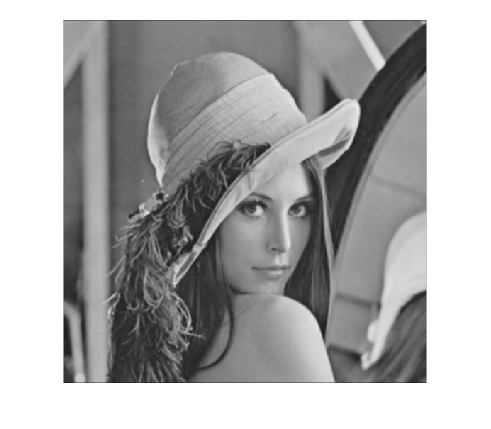

I = imread('lena_gray_512.tif');
h = [1 1 1; 1 1 1; 1 1 1];
h = h / sum(sum(h)); % filtres integratius, suma = 1
J = imfilter(I,h);
imshow(J)

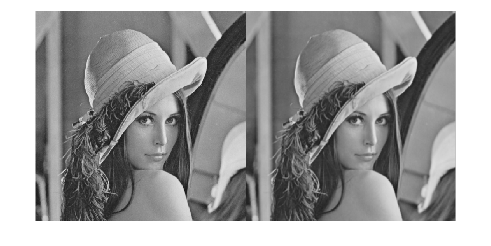

montage({I J})

### Filtre gaussià

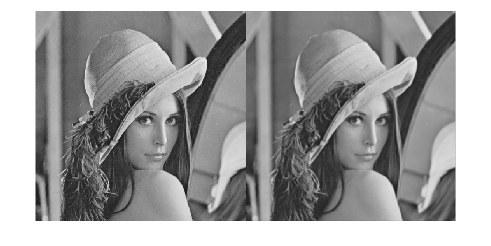

filterSize = 5;
h = fspecial("gaussian", filterSize, filterSize/5);
J = imfilter(I, h);
montage({I J})

### Filtre no lineal

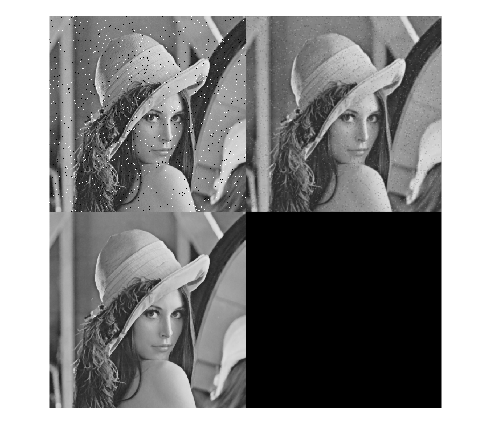

In = imnoise(I, "salt & pepper", 0.02);

filterSize = 5;
h = fspecial("gaussian", filterSize, filterSize/5);
Ig = imfilter(In, h);

Im = medfilt2(In, [3,3]);

montage({In Ig Im})

### Filtres passa alts

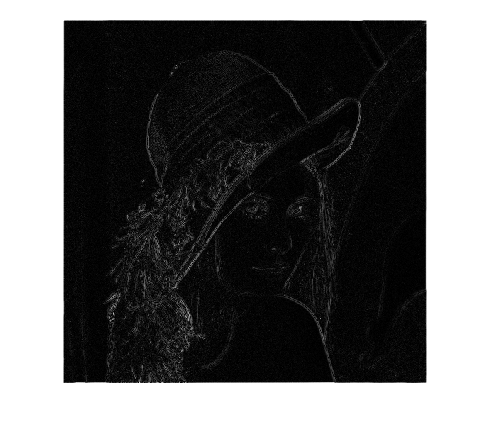

filterSize = 5;
h = fspecial("gaussian", filterSize, filterSize/5);
J = imfilter(I, h);

D = abs(double(I) - double(J));
imshow(D, [])

### Filtres derivatius

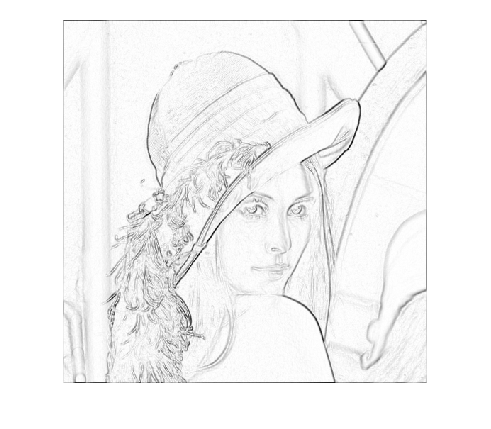

hx = [1 0 -1; 2 0 -2; 1 0 -1];
Gx = imfilter(double(I), hx);
hy = hx';
Gy = imfilter(double(I), hy);

Modul = abs(Gx) + abs(Gy);
imshow(imcomplement(Modul), [])

### Laplacia

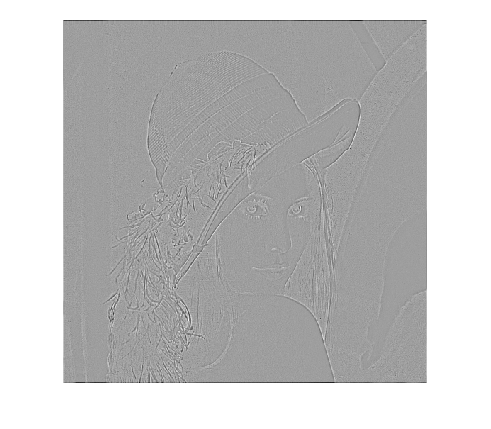

hL = [1 1 1; 1 -8 1; 1 1 1]; %laplacia -8
L = imfilter(double(I), hL);
imshow(L, []);

### Laplacian of Gaussian

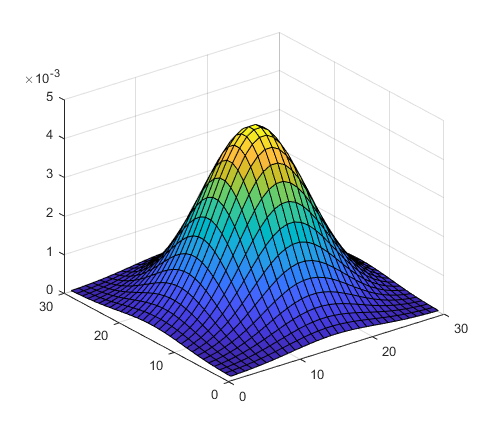

N = 30;
h = fspecial("gaussian", N, N/5);
[X Y] = meshgrid(1:N, 1:N);
surf(X, Y, h);

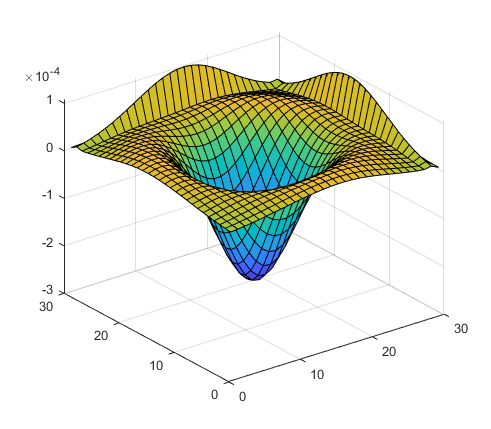


hx = [1 -1];
hy = hx';

dx = imfilter(h, hx, 'replicate');
dy = imfilter(h, hy, 'replicate');

dx2 = imfilter(dx, hx, 'replicate');
dy2 = imfilter(dy, hy, 'replicate');

hL = dx2 + dy2;

surf(X, Y, hL);

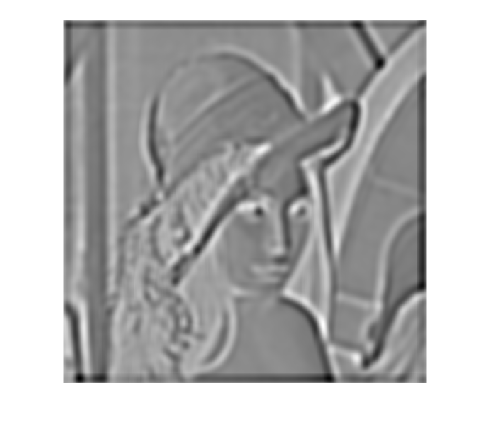


LL = imfilter(double(I), hL);
imshow(LL, []);

### Canny

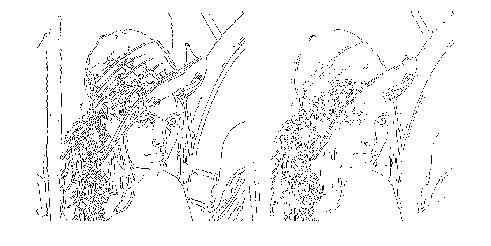

C = edge(I, "canny"); % aplica algoritme
Z = edge(I, "zerocross", 0.005); % deteccio de passos per zero amb llinda
montage({C, Z})

### Reflexió detectar contorns amb imatges amb color:

S'em ocudeixen varies maneres, el que faría jo es una de les seguents opcions:

- O bé detectar els contorns entre colors en parells, i despres operar amb aixo (vermell vs verd, verd vs blau,blau vs vermell)

- O bé distribuir els colors en diferents rangs de blanc (per ex vermell [0, 255], blau[256, 512], ...) per tal de quela diferencia de colors sigui comparable

- O bé agafar el component H de la versió HSV de la imatge per detectar els canvis